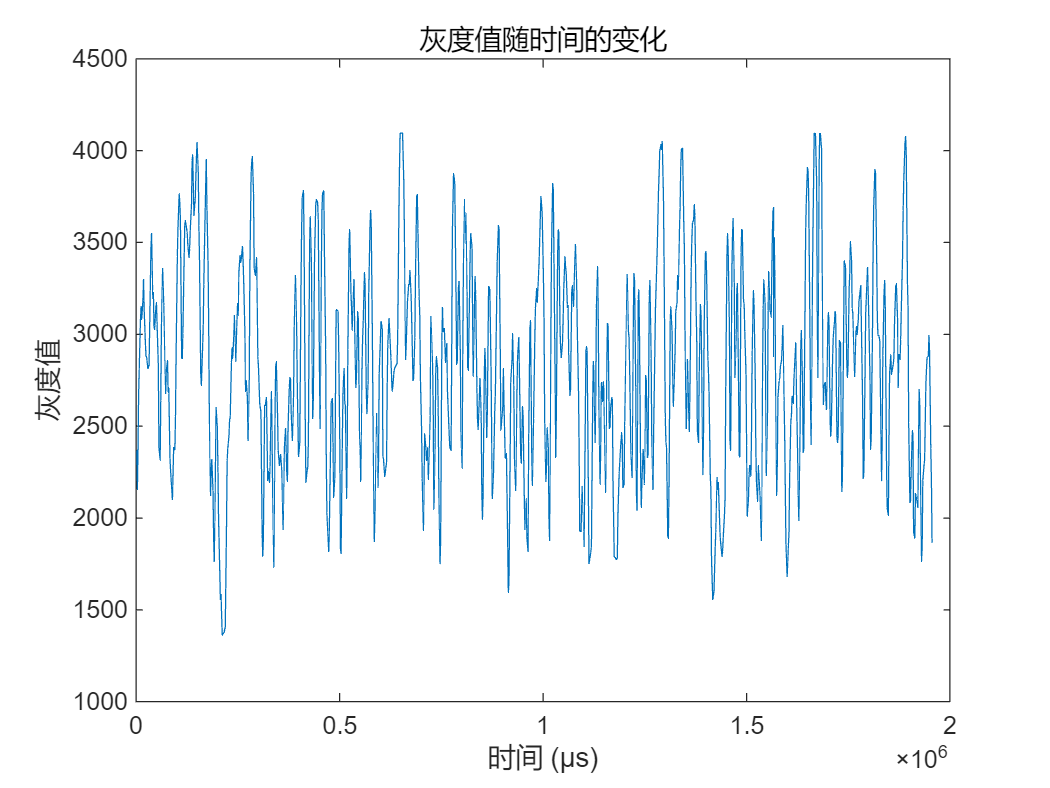

clear;

% % 指定文件路径
% file_path = 'D:\课题组\事件相机相关\实验\图片\2024.03.21\MipiData_20240321_094710842_EI_70M.csv';
% 
% % 使用 readmatrix 读取数据
% data = readmatrix(file_path);

% 指定文件路径
 matfile_path = 'First round of data filtering.mat';

% 使用load函数加载.mat文件
 loadedData = load(matfile_path);

% 获取加载的数据
data = loadedData.data_with_x_or_more_repeats;  
% data = loadedData.interpolatedData;

% 指定目标坐标
% target_row = (800 - 623); % mat文件的坐标原点在左下角，而matlab的坐标原点在左上角 ，换算的时候需要减去
target_row = 120;
target_col = 458;

% 通过逻辑索引筛选出目标坐标的数据
target_data = data(data(:, 1) == target_row & data(:, 2) == target_col, :);

% 按时间排序数据
sorted_data = sortrows(target_data, 5); % 假设时间列是第五列

% 添加序号列
% sorted_data(:, 6) = 1:size(sorted_data, 1);

% 显示筛选后的数据
% disp('Filtered data for target coordinates');
% disp(sorted_data);

% 绘制灰度随时间变化的图
% figure;
% plot(sorted_data(:, 5), sorted_data(:, 3), '.');
% xlabel('时间 (μs)');
% ylabel('灰度值');
% title('灰度值随时间的变化');

% 绘制灰度随时间变化的图
figure;
plot(sorted_data(:, 5), sorted_data(:, 3), '-');
xlabel('时间 (μs)');
ylabel('灰度值');
title('灰度值随时间的变化');



% 指定要保存的文件名
save_file_path = 'Second round of data filtering.mat';

% 保存数据到 .mat 文件
save(save_file_path, 'sorted_data');

disp(['数据已保存到文件 ', save_file_path]);

数据已保存到文件 Second round of data filtering.mat
